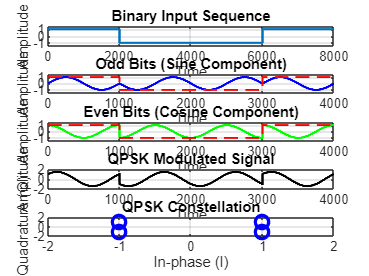

clc; clear; close all; 
 
% Input bit sequence  
bit_seq = [1 1 0 0 0 0 1 1];  
fc = 1; % Carrier frequency  
t = 0:0.001:1; % Time vector for each bit (1ms per bit) 
 
% Map bits for QPSK: 0 -> -1 
bit_seq(bit_seq == 0) = -1; 
 
% Separate even and odd bits 
b_e = bit_seq(2:2:end); % Even bits 
b_o = bit_seq(1:2:end); % Odd bits 
 
% Generate base waveforms 
cos_wave = cos(2 * pi * fc * t); % Cosine wave for even bits 
sin_wave = sin(2 * pi * fc * t); % Sine wave for odd bits 
 
% Generate modulated waveforms 
bec = kron(b_e, cos_wave); % Even bits modulated with cosine 
bes = kron(b_o, sin_wave); % Odd bits modulated with sine 
qpsk_signal = bec + bes; % QPSK modulated signal 
 
% Generate bit waveforms for plotting 
bit_wave = repelem(bit_seq, length(t)); % Full input bit waveform 
bit_e_plot = repelem(b_e, length(t) ); % Even bits for plotting 
bit_o_plot = repelem(b_o, length(t) ); % Odd bits for plotting 
 
% Plot results 
figure('Name', 'QPSK Modulation'); 
 
% Binary Input Sequence 
subplot(5, 1, 1); plot(bit_wave, 'LineWidth', 1.5); 
grid on; axis([0 length(bit_wave) -1.5 1.5]); 
title('Binary Input Sequence');xlabel('Time'); ylabel('Amplitude'); 
 
% Odd Bits (Sine Component) 
subplot(5, 1, 2); 
plot(bes, 'b', 'LineWidth', 1.5); hold on; 
plot(bit_o_plot, 'r--', 'LineWidth', 1.2); 
grid on; axis([0 length(bes) -1.5 1.5]); 
title('Odd Bits (Sine Component)'); 
xlabel('Time'); ylabel('Amplitude'); 
 
% Even Bits (Cosine Component) 
subplot(5, 1, 3); 
plot(bec, 'g', 'LineWidth', 1.5);hold on; 
plot(bit_e_plot, 'r--', 'LineWidth', 1.2); 
grid on; axis([0 length(bec) -1.5 1.5]); 
title('Even Bits (Cosine Component)'); 
xlabel('Time'); ylabel('Amplitude'); 
 
% QPSK Modulated Signal 
subplot(5, 1, 4); 
plot(qpsk_signal, 'k', 'LineWidth', 1.5); 
grid on;axis([0 length(qpsk_signal) -2 2]); 
title('QPSK Modulated Signal'); 
xlabel('Time'); ylabel('Amplitude'); 
 
% QPSK Constellation 
subplot(5, 1, 5); 
constellation = [1 + 1j, -1 + 1j, -1 - 1j, 1 - 1j];   
plot(real(constellation), imag(constellation), 'bo', 'MarkerSize', 8,'LineWidth', 2) ; 
grid on; axis([-2 2 -2 2]);title('QPSK Constellation'); 
xlabel('In-phase (I)'); ylabel('Quadrature (Q)');